# Practice 2: measurements and calibration

## 1. Variation of energy over time

### 1.1 Calculation of the Root Mean Square (RMS) value of a signal

The usual unit of measurement when working with electrical or sound signals is the root mean square (RMS) value.

The RMS value of a signal, in the interval [t1 t2], is $x_{eff}=x_{rms}= \sqrt{\overline{x^2}} = \sqrt{\frac{1}{T} \int_{t_1}^{t_2} x^2(t) \, \mbox{d}t}$, with T = t2-t1. If the signal is discrete, the RMS, in the interval [n1 n2], is estimated as:

            $\hat{x}_{rms}= \sqrt{\frac{1}{N} \sum_{n=n_1}^{n=n_2} x[n]^2 }$,

where N is the number of samples in the interval.

Define a new function with this header:

            *function outputRMS = MyRMScalculation(signal);*

and complete these lines in the body of the function so that it returns the RMS of the input signal:"

*            % RMS calculation. *

*            % Use the 'sum' command.*

*            % Do NOT use a 'for' loop.*

*            outputRMS = ?????*

Let's now test if it works as expected. When using as input:

outputRMS = MyRMScalculation((1:5).')

outputRMS = 3.3166

we should get as output:

        *    outputRMS =*

*                    3.3166*

Verify that this result corresponds to what you obtain when calculating it manually.

Generate a pure tone of 200 Hz for 5 seconds, with amplitude 1, starting at time t = 0 seconds. Assume a sampling frequency of 6 kHz. Store it in the variable *tone200Hz*.

% INSERT CODE HERE:
f1 = 200;
fs = 6e3;
t = (0:1/fs:5-(1/fs)).';
tone200Hz = cos(2*pi*f1*t);

Plot both the signal *tone200Hz* and its RMS value simultaneously. Use the *yline* command.

% INSERT CODE HERE:
 tone200Hz_rms = MyRMScalculation(tone200Hz);
 figure
 plot(t,tone200Hz);
 hold on;
 yline(tone200Hz_rms);

Plot only the first three periods using *xlim*.

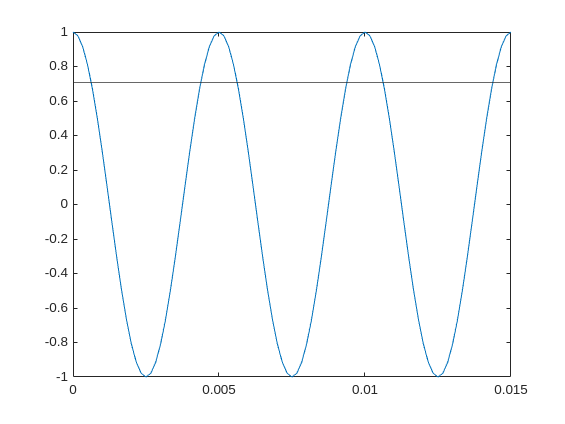

% INSERT CODE HERE:
xlim([0,3*(1/f1)]);

Load the signal *x2*, generated using the same sampling frequency that we are using.

% INSERT CODE HERE:
load x2.mat

Verify that we can use the same time axis *t  *as the signal *tone200Hz*.

% INSERT CODE HERE:
whos x2

  Name          Size             Bytes  Class     Attributes

  x2        30000x1             240000  double              



whos t

  Name          Size             Bytes  Class     Attributes

  t         30000x1             240000  double              



In these cases it may be convenient to use the command '*whos*' to check which variables you have loaded, what type they are, and their size.

Plot both the signal *x2* and its RMS simultaneously, as you did before with the *tone200Hz*.

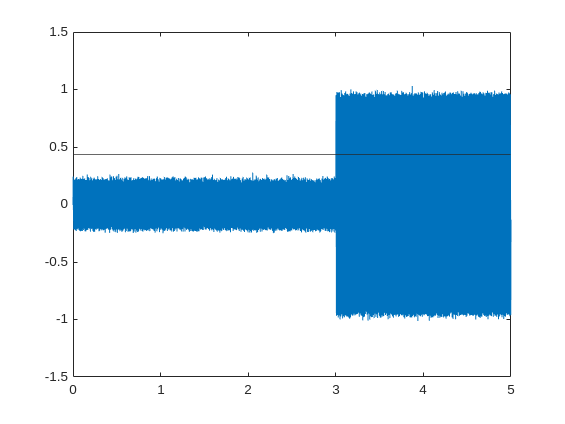

% INSERT CODE HERE:
 x2_rms = MyRMScalculation(x2);
figure
plot(t,x2);
hold on
yline(x2_rms);

Observe the beginning and the end of signal x2. Does the RMS value you have calculated make sense if we want to observe energy variations in the signal over time? Why?

No tiene sentido hacer el RMS de una señal entera que tiene muchos cambios de amplitud muy grandes, ya que, el RMS no sería representativo

What units does the 200Hz tone you just generated have? What units does the signal x2 you loaded have?

### 1.2 Incorporating the calculation of the root mean square value into our processing framework

When dealing with signals that may change their average amplitude over time, it is interesting to calculate their energy in shorter windows.

Since we already have a function that calculates the RMS value, we can integrate it into our frame processing framework.

Save the FrameProcessing function to a file named FrameRMScalculation, and modify its header:

*            function processedSignal = FrameRMScalculation(signal,Nframe, Noverlap)*

In this function, all we have to do is include the processing we want:

        *    % Here comes the frame processing*

*            processedFrame = MyRMScalculation(frameSignal)*

And that's it. Well, no, first we need to check if it works.

When calling the function with these values:

processedSignal = FrameRMScalculation((1:5)',2,1)

processedSignal =     1.5811    2.5495    3.5355    4.5277


we should obtain these values in the output *processedSignal*:

            *totalNframes =*

            *     5*

            *Frame number 1.....   1  2*

            *Frame number 2.....   2  3*

            *Frame number 3.....   3  4*

            *Frame number 4.....   4  5*

            *ans =*

            *    1.5811    2.5495    3.5355    4.5277*

Notice that it returns a single value for each processing frame, since the function MyRMScalculation is what does that.

In fact, if we processed the 200 Hz sine wave stored in the tono200Hz signal as a single frame, it should give us the expected theoretical value. Check it:

  processedSignal = FrameRMScalculation(tone200Hz,length(tone200Hz),0)

processedSignal = 0.7071

Calculate the theoretical root mean square value of a 200 Hz tone, with amplitude 1, in a continuous (analog) signal. Do we get the same value?

% INSERT CODE HERE:

% theoreticalRMSvalue = ????

Let's now calculate the root mean square value of the x2 signal that we had loaded, but now progressively along the signal. For example, with frames of 100 ms... how many samples should we choose?

% Insert code
fs = 6e3;
frameSize = 100e-3/(1/fs) 

frameSize = 600

Now analyze the RMS value of the x2 signal with that frame size, without overlap. Only represent the root mean square value, indicating its values with an asterisk:

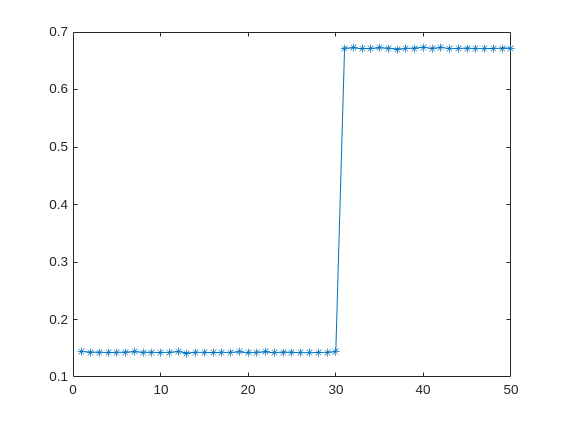

% Insert code
Noverlap = 0;
processedSignal = FrameRMScalculation(x2, frameSize, Noverlap);
figure; plot(processedSignal,'-*'); shg;

Does this way of calculating the root mean square value better represent what happens in the signal? Discuss why.

**EXTRA:**

Try to represent both the waveform of the x2 signal and the result of the root mean square value over time. What problem do you encounter? How would you solve it to be able to represent them in the same figure?

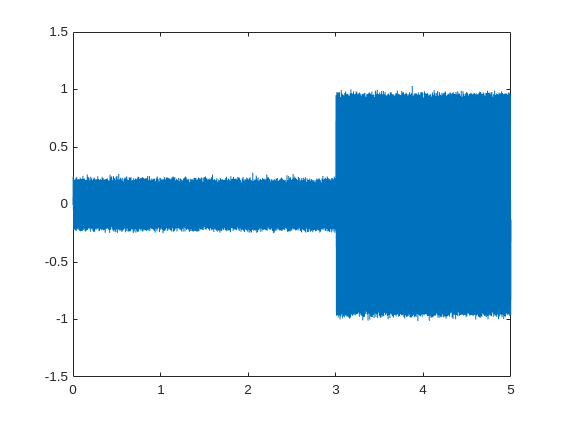

% Insert code
t2 = (0:(frameSize-Noverlap)*(1/fs):(length(processedSignal)-1)*((frameSize-Noverlap)*(1/fs)));
figure();plot(t,x2);

holB on; plot(t2, processedSignal, '-*'); 

Unrecognized function or variable 'holB'.

### 1.3 Summary

In section 1 we have:

- calculated the root mean square value of a signal.

- programmed a function FrameRMScalculation(...), using our frame processing framework, to calculate the evolution of the root mean square value along the signal.

## 2. Calibration

### 2.1 Measurement system: ananlog and digital systems

When we want to use a digital processing system to analyze a signal, we always have a part that works with analog (continuous) signals, which we can call an **analog system**, and a part that works with discrete and quantized signals, which we can call a **digital system**.

The analog system acts as a front-end, converting the physical variable we want to measure into an electrical signal. The digital system converts this electrical signal into a discrete and quantized signal (what we usually call a **digital signal**), on which it will perform its calculations. 

This is done by the so-called analog-to-digital converter (ADC). Usually, measurement systems do not reconstruct an analog signal again, although this would be possible using a digital-to-analog converter (DAC).

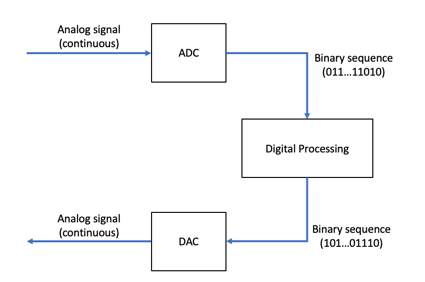

### 2.2 Analog System: Acoustic-electric transduction and microphone sensitivity 

If we want to measure acoustic signals, the first thing we must do is convert them into an electrical signal. This is achieved using a microphone, which is a transducer that converts acoustic energy into electrical energy. 

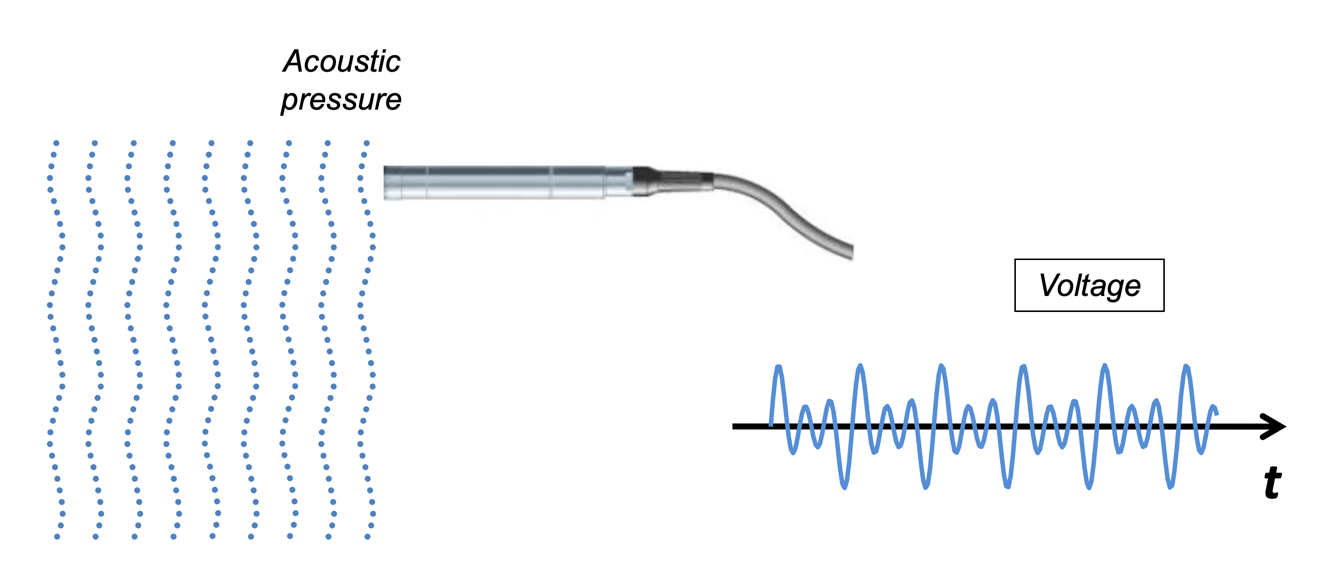

That transduction is primarily defined by what we call **S**, the **sensitivity of the microphone**. This sensitivity relates the electrical energy obtained when exciting the microphone with a specific acoustic energy thanks to the following formula:

        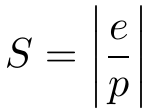

where ***e*** is the voltage obtained when presenting the microphone to a sound pressure ***p***. **RMS values are always considered.**

**The sensitivity S depends on both the working frequency and the angle of arrival of the acoustic wavefront** at the microphone, as microphones are often directional, meaning their sensitivity varies with the angle of arrival and frequency. We can say that the sensitivity of the microphone, S, can be calculated taking into account three elements:

-  The **nominal sensitivity**, which is the sensitivity of the microphone on its acoustic axis (0º arrival angle), at 1 kHz. This parameter can be expressed in both natural units, mV/Pa, and logarithmic units dBV/Pa.

-    The frequency response on the acoustic axis (0º arrival angle). This is the so-called "**frequency response**". Typically expressed in dB.

-    The variation with frequency and arrival angle. This is the "**directivity** **pattern**" or "**polar response**". Typically expressed in dB.

These three elements are combined as follows if we are using logarithmic units:

        

For example, suppose we have a microphone with a nominal sensitivity (0º, 1kHz) of S = 1.6 mV/Pa and its specifications are:

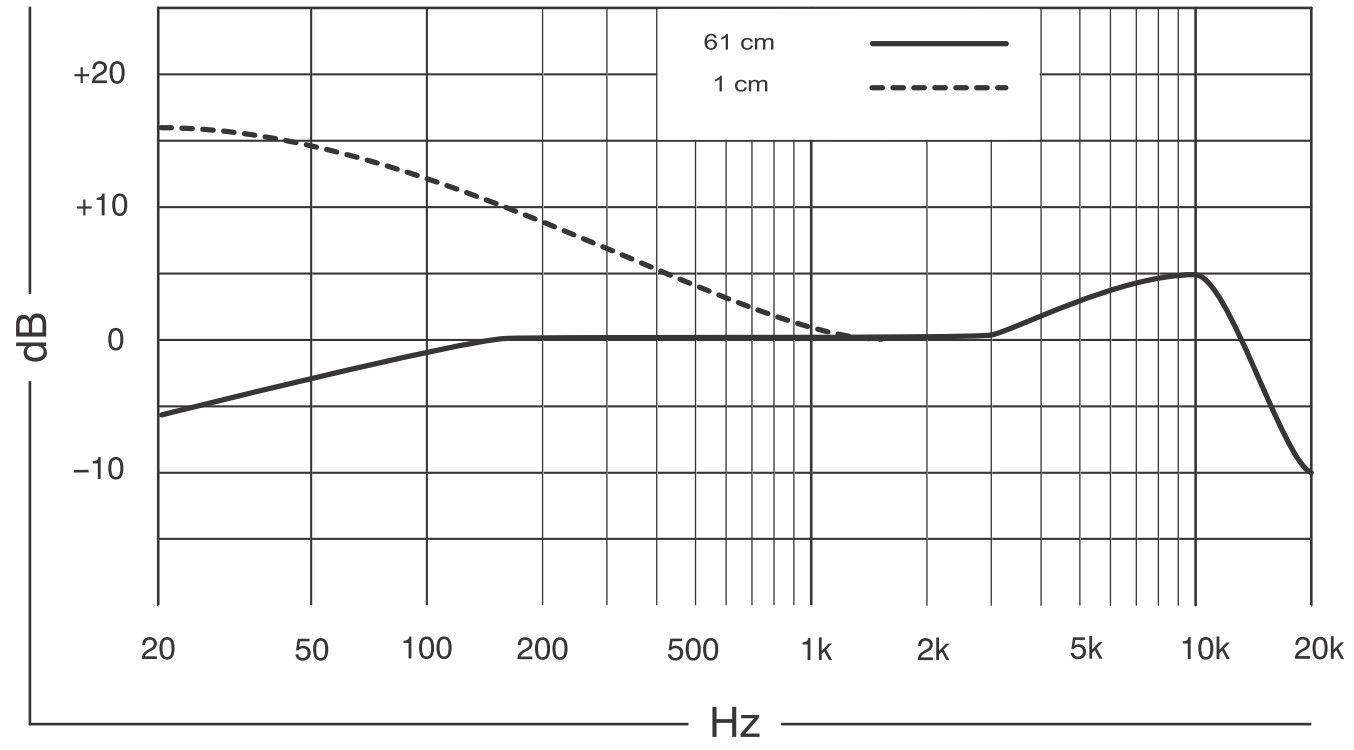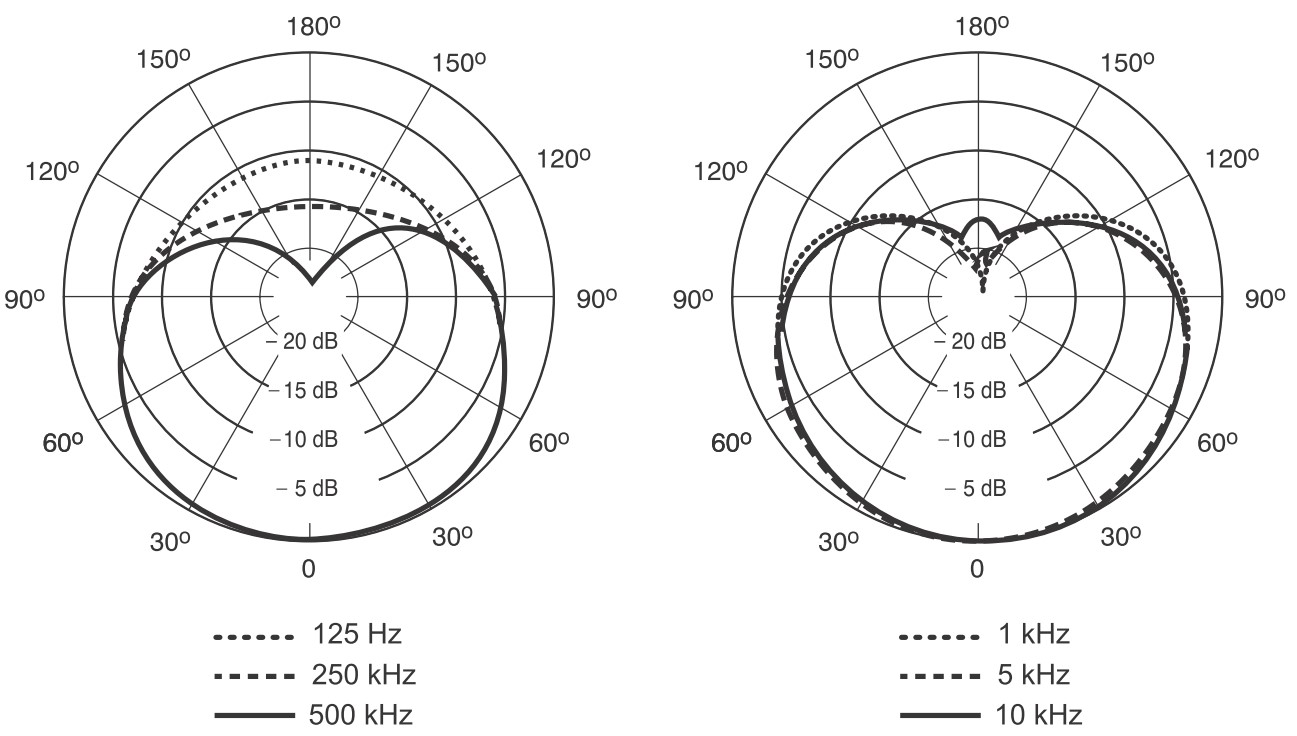

**Let's calculate its sensitivity S for a frequency of 10 kHz and an arrival angle of 120º. We assume a distance to the sound source greater than 61 cm, so the***** proximity effect***** does not affect the microphone. **

First, let's initialize these variables, which correspond to the nominal sensitivity in natural units, *S_1kHz_un*, in V/Pa, and the variations in decibels due to the working frequency and arrival angle. Approximate these variations to the nearest integer value in decibels. Indicate in each operation the units of the value, using a Matlab comment at the end.

% Insert code
S_1kHz_un = 1.6e-3;  % V/Pa
deltaS_f = 5;      % dB
deltaS_theta = -10;   % dB

First, let's convert the nominal sensitivity to logarithmic units, to dBV/Pa, for example.

% Insert code
S_1kHz_log = 20*log10(S_1kHz_un);  % dBV/Pa

To calculate the total sensitivity, we just have to sum the corresponding terms.

% Insert code
S_log = S_1kHz_log+deltaS_f+deltaS_theta  % dBV/Pa

Make sure the result is S_log = -60.9176 dBV/Pa. In the checks, we will use several decimals to avoid accumulating calculation errors, but in the specification sheets, values are not indicated with such precision.

### 2.3 Connection between the analog system and the digital system

The electrical output signal from the microphone typically passes through a gain adjustment G, to allow what is called its ***calibration***, which we will see shortly.

Therefore, the system we will work with will be similar to this one:

                    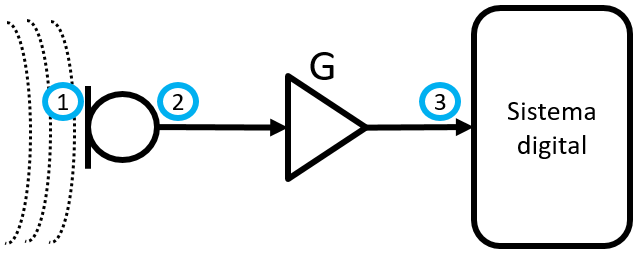

At point 1, we will have sound pressure, point 2 will be the microphone output, and therefore, an electrical signal, and point 3 will also remain an electrical signal. All are analog (continuous) signals.

Let's now assume that the microphone is the one presented in section 2.2. **We want to know what voltage will appear at point 3, in dBV, at the input of the digital system, if we present a 1 kHz tone with a sound pressure level of 94 dB at point 1.** The gain G of the amplifier is 3 dB.

First, we need to know the voltage at point 2, for which we need to apply the microphone sensitivity to the pressure it is exposed to.

 Calculate the microphone sensitivity. Indicate in each operation the units of the value, using a Matlab comment at the end.

% Insert code
S_1kHz_un = 1.6e-3;  % V/Pa
S_1kHz_log = 20*log10(S_1kHz_un);%dBV
deltaS_f = 0 ; % dB
deltaS_theta = 0;  % dB
S = S_1kHz_log+deltaS_f +deltaS_theta% dBV/Pa
S_un=10^(S/20);%V/Pa

Calculate the voltage, in natural units, at point 2. Indicate in each operation the units of the value, using a Matlab comment at the end.

% Insert code
L_p1 = 94; % dBSPL
p_1 = sqrt(10^(L_p1/10)*(2*10^(-5))^2) % Pa
e_2 = p_1*S_un % V

Calculate the voltage at point 3. Indicate in each operation the units of the value, using a Matlab comment at the end.

% Insert code
G_log = 3; % dB
e_2_log = 20*log10(e_2); % dBV
e_3_log = e_2_log + G_log % dBV

Make sure your result matches *e_3_log = -52.8970 dBV*.

### 2.4 Dynamic range in the digital system

Let's remember that to define the dynamic range of a system, we must set the following parameters:

- Maximum useful value: this value defines the beginning of the so-called **clipping zone**. Any value higher will be "useless", either because it will be truncated to this maximum value or because its distortion is so great that the output is not considered valid for the application.

- Minimum useful value: any value lower than this will be "useless", either because it will be replaced by this minimum value or because the existing background noise makes the output invalid for the application.

- Headroom: The signal level at each moment can vary, but the so-called nominal level is usually defined, which is the working level for which the characteristics of the equipment are usually specified. The difference between the maximum useful value and this nominal level is called headroom.

- Signal-to-Noise Ratio (SNR): The difference in levels between the signal level and the background noise tells us if we have reasonably low background noise at each moment.

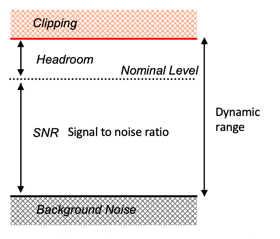 

In a digital system, its dynamic range can also be defined as follows:

- Maximum useful value (***x_max***�): This is the maximum representable value. It is usually considered normalized, so it is typically an absolute value of "1" in natural units. 

- Minimum useful value: This is the minimum representable value in absolute terms. It is usually "0" in natural units.

- Headroom: This is not usually specified in advance and is typically determined by the application. It establishes the relationship with a nominal value of the application: ***x_nom***�.

- Signal-to-Noise Ratio (SNR): This is usually defined between the maximum and minimum representable values, considering the number of bits dedicated to represent each value.

 And the relationship with its analog values is usually established as follows (in natural units):

where *e_max*� is the maximum voltage value considered in the application, and *e_nom* is the nominal value.

As it is a direct correspondence between the values, the proportions between the values are maintained in natural units in this assignment:

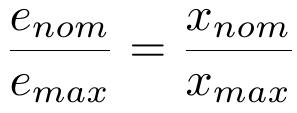

which, in logarithmic units, leads to a very simple expression:

This digital signal, *x*, is what we will have at point 4 in the figure, once it has passed through the analog-to-digital converter, within the digital part of the measurement system.

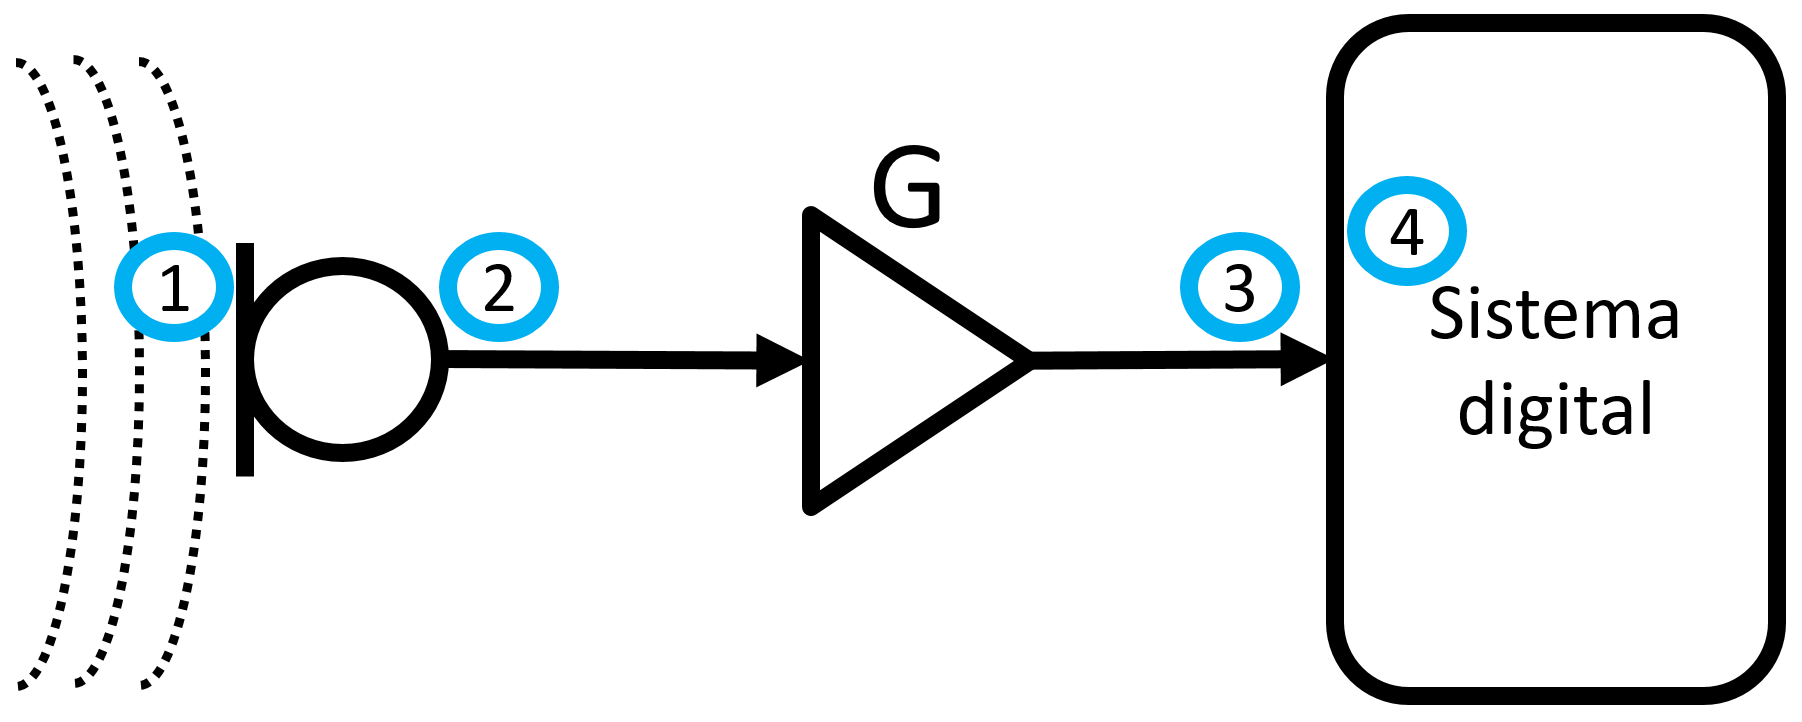

Let's assume, for the example we are considering, that the nominal level will coincide with that reference pressure of 94 dB sound pressure level at point 1, and that the maximum representable value in the digital part corresponds to 0 dBFS. If we define a headroom of 12 dB, what will be the maximum pressure, in Pascals, that we can represent in the digital system without experiencing clipping? Indicate in each operation the units of the value, using a Matlab comment at the end.

% Insert code
headroom = 12;  % dB
L = 94;
p0=2*10^(-5);
x_max_log = 0;  % dBFS
x_nom_log = x_max_log - headroom;  %dBFS
p_nom_1= sqrt(10^(L/10)*p0^2);
e_nom_2=20*log10(p_nom_1*S_un);
e_nom_log =  e_nom_2+G_log% dBV
e_max_log = e_nom_log + headroom;  % dBV
e_max_2=e_max_log-G_log;
p_1_max = 10^((e_max_2)/20)/S_un % Pa

Make sure your result matches *p_1_max = 3.9905 Pa*.

Remember the definition of sound pressure level:

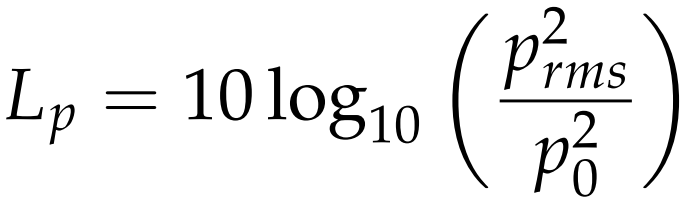

Now calculate, in decibels, the difference between the maximum sound pressure level and the nominal sound pressure level that the measurement system can handle. Relate it to the headroom of the digital system and explain why they have that relationship. Indicate in each operation the units of the value, using a Matlab comment at the end.

% Insert code
L_p_1_max = 10*log10(p_1_max^2/(2*10^-5)^2) %% dBSPL
difference_log = L_p_1_max - 94  %% dB

Make sure your result matches difference*_log = 12 dB*.

### 2.5 Summary

In section 2 we have:

- reviewed how a measurement system typically looks today: an analog and a digital system.

- calculated the microphone sensitivity and its dependency on the working frequency and sound arrival angle.

- obtained the voltage value at the input of the digital system after passing through an amplifier.

- established the relationship between the values of the analog and digital systems, relating them to the dynamic range, their nominal and maximum values, and the headroom.

## 3. Filter banks

In measurement equipment, one of the common ways to estimate energy in different frequency bands is by using what is called a **filter bank.** A filter bank with N bands generates N different signals, each of which collects the energy of the filter's passband.

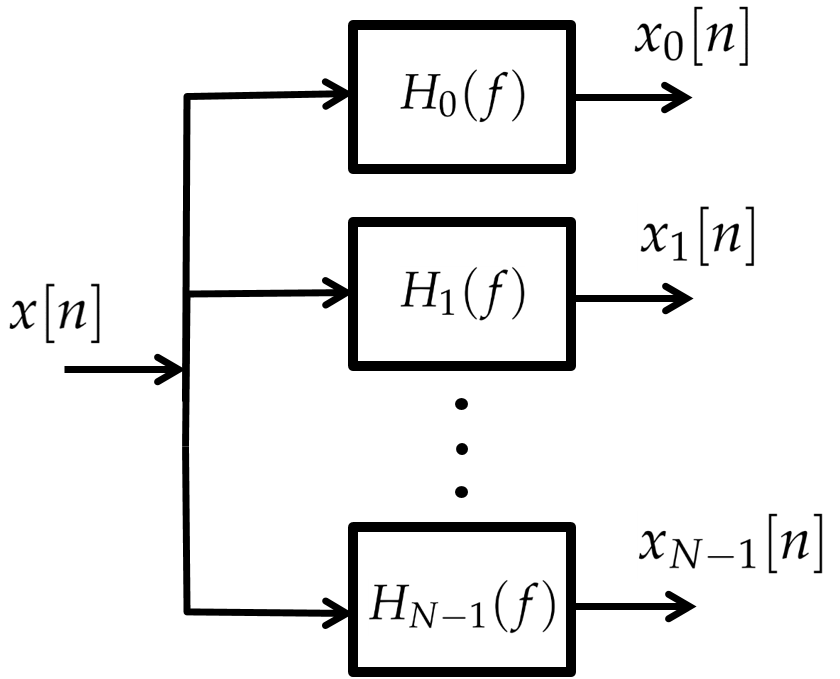

### 3.1 Representing filter banks with constant quality factor

Load file *FilterBankCoefficientsOctave.mat* which contains two variables, *FilterBankCoefficients_1_octave* and *FilterBankCoefficients_1_3_octave*. These are two processing objects from Matlab's Audio Toolbox, each containing the coefficients that implement the filter bank and can be used for filtering.

 load FilterBankCoefficientsOctave.mat

Use the *DrawFilterBankResponse* function to plot the response of the filter bank with a linear frequency axis. First, observe its help documentation:

 help DrawFilterBankResponse

 function DrawFilterBankResponse(auxFilterBankCoefficients, type);
    auxFilterBankCoefficients: an Octave Filter Bank block from the Audio
        Toolbox, that decomposes a signal into octave or fractional-octave subbands
    type: either 'log' or 'linear'
  Assumes:
    sampling frequency: 48 kHz
    reference frequency: 1 kHz



Plot the frequency response of the 1-octave filter bank with a linear frequency axis. Observe where the center frequencies are placed relative to the filter. Are they right in the center of the filter's passband? Why?

% INSERT CODE
DrawFilterBankResponse(FilterBankCoefficients_1_octave, 'linear');

fvtool requires Audio Toolbox.

Error in DrawFilterBankResponse (line 79)
fvt = fvtool(auxFilterBankCoefficients);%fvtool(auxFilterBankCoefficients,"NFFT",2^16);

Now, plot the frequency response of the 1-octave filter bank with a logarithmic frequency axis.

% INSERT CODE
% DrawFilterBankResponse(FilterBankCoefficients_1_octave, 'log');


Retrieve the center frequencies as:

centerFrequencies = FilterBankCoefficients_1_octave.getCenterFrequencies

and the edge frequencies:

bandEdgeFrequencies = FilterBankCoefficients_1_octave.getBandedgeFrequencies

Compare these values with the figures representing the filter bank.

### 3.2 Filtering a signal with a filter banks with constant quality factor 

Generate a pure tone of 1000 Hz for 5 seconds, with an amplitude of 1, starting at time t = 0 seconds. Assume a sampling frequency of 48 kHz. Save it in the variable `tone1kHz`.

% INSERT CODE HERE:
f1 = 1e3;
fs = 48e3;
t = (0:(1/fs):5-(1/fs)).';
tone1kHz = cos(2*pi*f1*t);

Now let's filter it using a **one-third octave band filter bank**.

tone1kHz_1_3_filteredMatrix = FilterBankFiltering(tone1kHz, FilterBankCoefficients_1_3_octave, 1);

What is the size of the `tone1kHz_1_3_filteredMatrix` matrix? Are the signals corresponding to each band in the rows or columns of the matrix?

Cada salida de filtro la tengo guardada en cada columna que tiene 240000 muestras.

% INSERT CODE HERE:
centerFrequencies1 = FilterBankCoefficients_1_3_octave.getCenterFrequencies
size(tone1kHz_1_3_filteredMatrix)

Draw the first 1000 samples of the signal corresponding to the first band, the first 1000 samples of the signal from the 14th band, and the first 1000 samples of the signal from the 17th band. Use `subplot` to draw all three at once.

% INSERT CODE HERE:
figure;
subplot(311);plot(t(1:1000),tone1kHz_1_3_filteredMatrix(1:1000,1));title('Band 1');
subplot(312);plot(t(1:1000),tone1kHz_1_3_filteredMatrix(1:1000,14));title('Band 14');shg
subplot(313);plot(t(1:1000),tone1kHz_1_3_filteredMatrix(1:1000,17));title('Band 17');shg

Check the cutoff frequencies and center frequencies of each band represented in the previous figure.

% Vector with edge frequencies
cut_frec_1_3 = FilterBankCoefficients_1_3_octave.getBandedgeFrequencies;
% Vector with central frequencies
central_frec_1_3 = FilterBankCoefficients_1_3_octave.getCenterFrequencies;
% INSERT CODE HERE:
disp(cut_frec_1_3(1));
disp(central_frec_1_3(1));
disp(cut_frec_1_3(14));
disp(central_frec_1_3(14));
disp(cut_frec_1_3(17));
disp(central_frec_1_3(17));

**What type of signal does each band signal contain? What amplitude do they have? Why do these signals appear in bands so far from the 1 kHz tone???????**

**EXTRA:?????**

Repeat the band filtering, but indicate that the group delay of the bands is not compensated. Draw the beginnings of the signals from bands 1, 14, and 17, and discuss what happens.

### 3.3 Estimation of the level of each band in the filter bank

A commonly used way to represent spectral energy, after filtering with a filter bank, is to calculate the RMS value of the signal corresponding to each band.

Calculate the rms value of each band of the 1 kHz tone that we filtered before, `tone1kHz_1_3_filteredMatrix`, group them into a vector `bands_rms`, and represent them all together using the `bar` function.

% INSERT CODE HERE:
% bands_rms is a column vector with the RMS value of the signal for each band.
x = MyRMScalculation(tone1kHz_1_3_filteredMatrix);  

Unrecognized function or variable 'tone1kHz_1_3_filteredMatrix'.

bands_rms = x' ;
figure; bar(bands_rms); shg

What is the rms value of the band with the highest energy? What tone amplitude does it correspond to?

Let's create a function `SPL_1_3_octave` that represents the sound pressure level (SPL) in one-third octave bands of the digital signal obtained when measuring a sound. Integrate the code you programmed earlier.

We will need the following input parameters:

    -> digital signal, values limited between -1 and +1.

    -> dBFS value corresponding to the digital signal when measuring 94 dB SPL at the system input.

In addition to displaying the graph, it should return a vector with the SPL values in dB for each one-third octave band:

*        output_SPL_1_3_octave = SPL_1_3_octave(input_signal, ref_dBFS_94_dB_SPL);*

Try it with a signal *tone1kHz*, defined in section 3.2:

% INSERT CODE HERE:
ref_dBFS_94_dB_SPL = -12;  %dB es -12 = 94 porque el valor máximo es 0dBFS = 106dBSPL
output_SPL_1_3_octave = SPL_1_3_octave(tone1kHz, ref_dBFS_94_dB_SPL);

Make sure that the band with the maximum sound pressure level has 106 dB SPL, which is the maximum value the system can handle without clipping, as we calculated before.

Load the signal contained in `tonos_3_4_5.wav`. Let's assume that it is the signal obtained in the digital system when we take a measurement with our system.

[tones_3_4_5, fs_3_4_5] = audioread('tones_3_4_5.wav');

Represent with a bar graph the sound pressure level (SPL) we have measured using a one-third octave filter bank.

% INSERT CODE HERE:
ref_dBFS_94_dB_SPL = -12;  %dB
output_SPL_1_3_octave = SPL_1_3_octave(tones_3_4_5, ref_dBFS_94_dB_SPL);

Make sure the result is approximately 79.97 dBSPL, 72.08 dBSPL, and 78.04 dBSPL for the 500 Hz, 1 kHz, and 2 kHz bands, respectively.

**E X T R A:**

Estimate the amplitudes of the tones that make up the `tonos_3_4_5` signal.

% L = 106;
% dato = L - 94 + REF;
% x_rms = sqrt(10^dato * x_rms_max^2);
% A= x_rms*sqrt(2);

### 3.4 White noise and pink noise

Suppose now that the input signal to the digital system is the one contained in the file noise1`.wav`. Discuss whether this signal is white noise or **pink noise.**

%INSERT CODE HERE
[noise1, fs1] = audioread('noise1.wav');
ref_dBFS_94_dB_SPL = -12;
noise1_SPL_1_3_octave = SPL_1_3_octave(noise1, ref_dBFS_94_dB_SPL);

Suppose now that the input signal to the digital system is the one contained in the file `ruido2.wav`. Discuss whether this signal is **white noise** or pink noise.

%INSERT CODE HERE
[noise2, fs2] = audioread('noise2.wav');
ref_dBFS_94_dB_SPL = -12;
noise2_SPL_1_3_octave = SPL_1_3_octave(noise2, ref_dBFS_94_dB_SPL);

### 3.5 Summary

In section 3 we have reviewed:

- non-uniform filter banks of constant quality.

- how to filter a signal using a filter bank.

- how to calculate and display the energy contained in each of the bands.

- how the energy of white noise and pink noise is distributed in a filter bank of constant quality

## 4. Examples of calibration

### 4.1 Presentation on screen of a measurement

The measurement system from section 2 has been calibrated so that when we have a sound pressure level of 94 dB at its input, we have a nominal level of -12 dBFS in the digital system, as we have set the maximum value to correspond to 0 dBFS and have 12 dB of headroom.

Suppose the digital system has to display the pressure level it is measuring:

value_SPL = 94; disp(['Measured SPL: ' num2str(value_SPL)  ' dBSPL']);

Indicate the necessary commands to obtain the sound pressure level value to be displayed on the screen, given a value in dBFS in the digital system. Test it with the value -17.32 dBFS. Indicate in each operation the units of the value, using a Matlab comment at the end.

% INSERT CODE HERE:
value_dBFS_max = 0;
headroom = 12; % dB
value_dBFS_nom = value_dBFS_max - headroom;  % dBFS
value_SPL_calibr = 94;  % dBSPL
value_dBFS = -17.32;  % dBFS
value_SPL = value_SPL_calibr + (value_dBFS - value_dBFS_nom)  % dBSPL
disp(['Measured SPL: ' num2str(value_SPL)  ' dBSPL']);

Make sure the result is *value_SPL = 88.68 dBSPL*.

### 4.2 Calibration of the system and measurement process

The measurement system, especially in its analog part, can have changes in its characteristics due to variations in temperature, humidity, and other factors. That's why, when we are going to take a measurement, the first thing is to** calibrate the system**. Let's see what happens if we don't do it and how to avoid it.

We continue working with the previous measurement system:

First, let's prepare a function that combines the calculations we have been doing and calculates the voltage generated at point 3, given a sound pressure at point 1.

Create a new function with this header:

            *function voltage_3 = MyVoltage3calculation(pressureRMS, sensitivity_V_Pa, G_dB);*

where `pressureRMS` is the rms value of the sound pressure signal recorded at point 1, `sensitivity_V_Pa` is the microphone sensitivity (total) in V/Pa, and `G_dB` is the gain of the amplifier in dB.

Complete these lines in the body of the function to return `voltage_3`, the RMS value of the voltage at point 3. Make use of everything you have worked on in previous sections:

*            % voltage_2 = ???*

*            % voltage_2_dB = ???*

*            % voltage_3_dB = ???*

*            % voltage_3 = ???*

Make sure that, for example, if `pressureRMS`` = 1.0024 Pa`, `sensitivity_V_Pa`` = 1.6e-3`, and `G_dB`` = 3`, the result is approximately `voltage_3`` = 0.0023 V`, as we had previously solved.

**What happens if the calibrated measurement system changes in some way? How can we recalibrate it?**

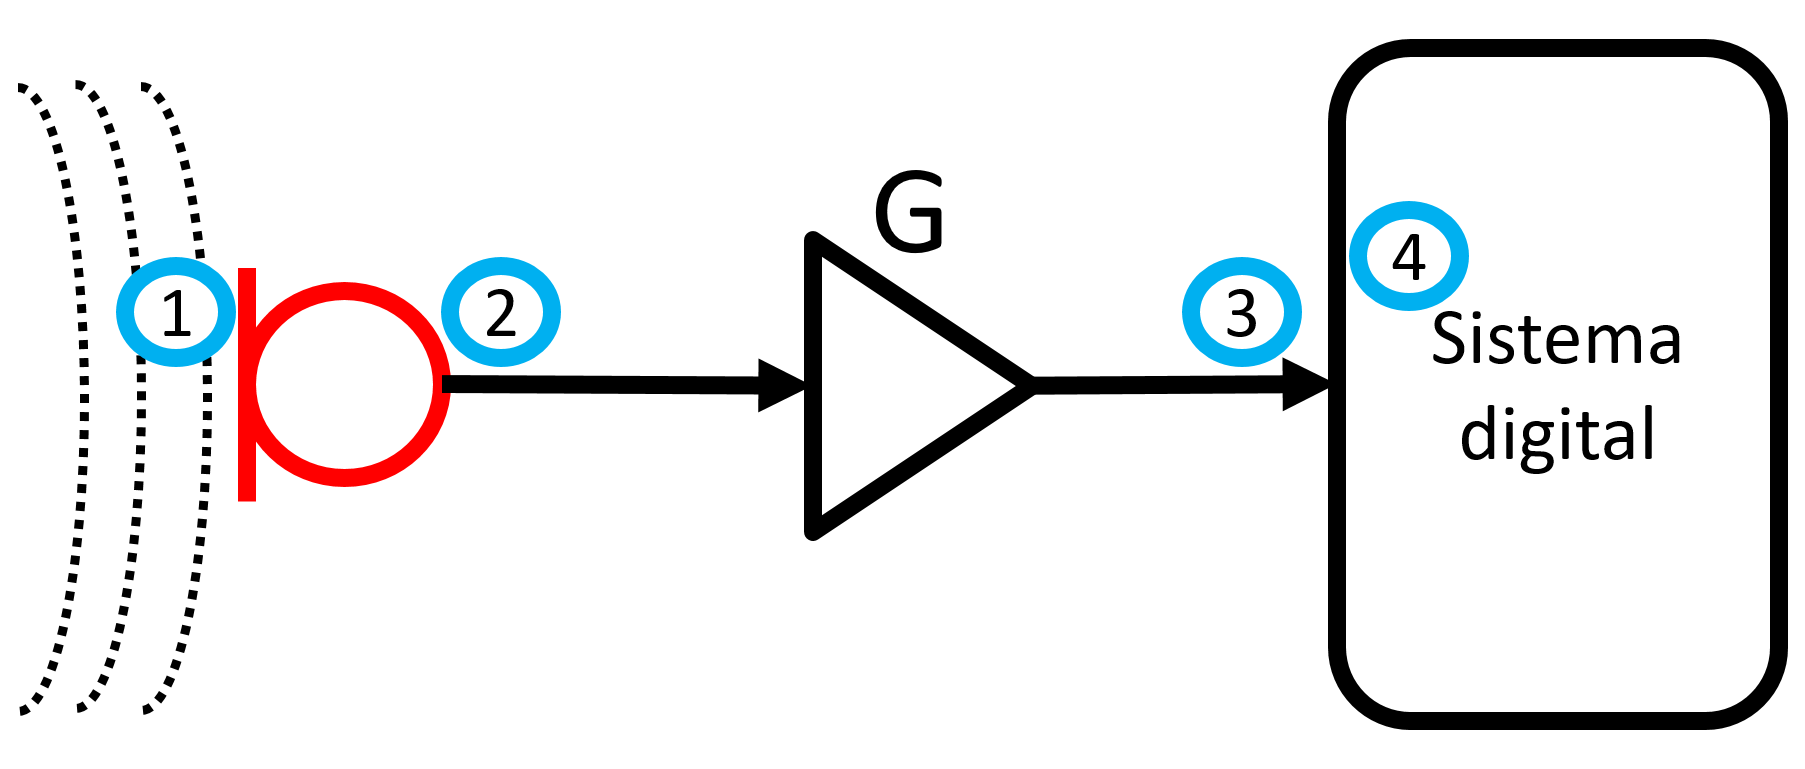

Now, suppose we change the microphone in the measurement system we have, and when we measure a 1 kHz tone with a sound pressure level of 94 dB, we obtain at the output of the microphone (point 2) an RMS voltage value of 14.1 mV. Adjust the amplifier gain, to a new value `G_new`, so that the voltage at point 3 is the value of `e_nom_log` (approximately 0.0023 V), as we had previously solved. What sensitivity do we have in the new microphone at its acoustic axis at 1 kHz? Indicate in each operation the units of the value, using a Matlab comment at the end.

% INSERT CODE HERE:
e_2 = 14.1e-3;  % V
e_2_log = 20 * log10(e_2);  % dBV
e_nom = 10^(e_nom_log/20);  %V   cojo el e_nom_log de la sección 2 para que sea más exacto
e_3 = e_nom;  % V
e_3_log = 20 *log10(e_3);  %dBV
G_new = e_3_log - e_2_log  % dB
S = e_2/p_1  % V/Pa

Make sure the result is `G_new`` = -15.8814 dB` and the sensitivity is `14.1 mV/Pa`.

Now, suppose you measure an acoustic tone of 1 kHz with an RMS pressure value of **0.3 Pa.** Display the result of the measurement in the current digital system, with the new microphone, after passing through all the systems. Verify that the measurement printed in the console matches the expected one.

% INSERT CODE HERE:
pressure_rms = 0.3;  % Pa
sensitivity = S;  %   V/Pa
voltage_3 = MyVoltage3calculation(pressure_rms, sensitivity, G_new) %   V
e_3_log = 20*log10(voltage_3) % dBV
difference_dB = e_3_log - e_nom_log %  dB diferencia de lo conseguia antes y ahora
value_dBFS_max = 0;  % dBFS
headroom = 12; % dB
value_dBFS_nom = value_dBFS_max - headroom;  % dBFS
value_SPL_calibr = 94;  % dBSPL
measured_value_dBFS = value_dBFS_nom + difference_dB % dBFS
measured_value_SPL = value_SPL_calibr + difference_dB; %  dBSPL
disp(['Measured SPL: ' num2str(measured_value_SPL,'%.1f')  ' dBSPL']);
input_value_SPL = 10*log10((pressure_rms^2)/(20*10^-6)^2); %  dBSPL
disp(['SPL at input: ' num2str(input_value_SPL,'%.1f')  ' dBSPL']);

### 4.3 Resumen

In section 4 we have reviewed:

- how to display a result in dB SPL on the console, given a value in dBFS, considering the system's calibration

- how to recalibrate a system if there are changes in its elements

- how to display the result in dB SPL on the console, given a sound pressure at the input, passing through the complete measurement system (analog and digital).